# H2

A partir de la imatge 'rabbit.jpg' , es demana que entregueu un pdf  amb el codi matlab i les imatges resultants que resolgui el següent:

- Obtenir una imatge binària de contorns a partir de la imatge resultat  del filtratge laplacià fet a classe . Cal mostrar els passos per zero  del laplacià.

Es recomena usar operacions vectoritzades, però no podeu usar cap funció de detecció de passos per zero implementada per altres.

Treballeu amb veinatge-4

- Us surt una imatge de contorns molt sorollosa? Utilitzeu la imatge del  gradient obtinguda a classe per a elininar aquest soroll:

De la imatge obtinguda, elimineu tots aquell píxels de contorn que no tinguin un gradient mínim. Mostreu la imatge resultat.

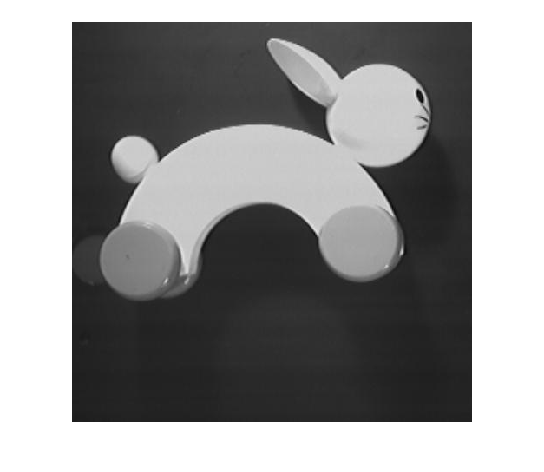

I = imread('rabbit.jpg');
imshow(I);

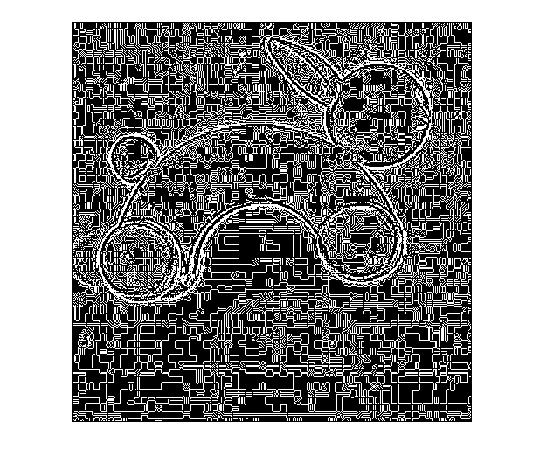

% gradient Laplacià
hl = [0 1 0; 1 -4 1; 0 1 0];
Gl = imfilter(double(I), hl);
imshow(Gl);

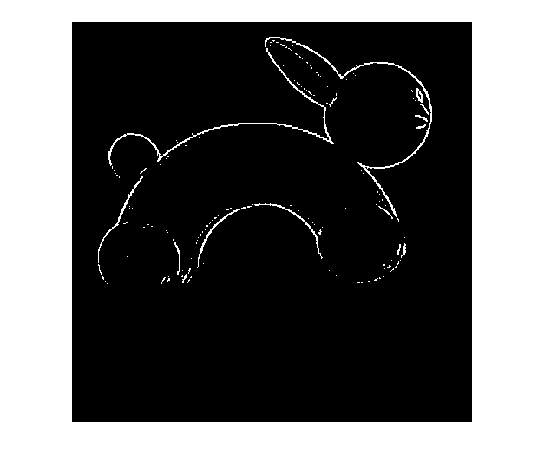

% filtre Gaussià
N = 2;
h2 = fspecial("gaussian", N, N/6);
J2 = imfilter(Gl, h2);
% eliminar píxels que no tenen un gradient mínim
J2 (J2 < 10) = 0;
J2 (J2 > 0) = 1;
imshow(J2);